# Hunt for a sensible LQI solution - part 1

Load the Linearised quadcopter+pendulum model

load('bh_SAVED_LIN_PLANT.mat')
size(my_LIN_PLANT)

State-space model with 3 outputs, 4 inputs, and 18 states.


## Control design:

We'll use the approach described by the LQI() function, ie::

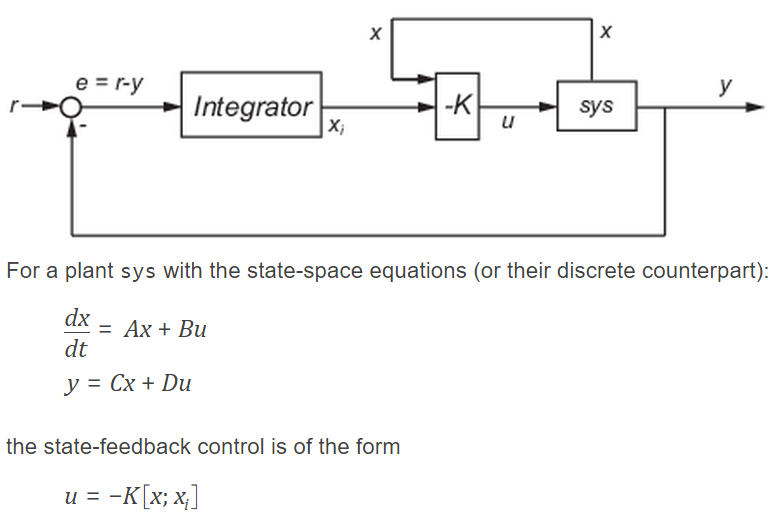

Note that:  

- 
$$K\in R^{N_u \times \left(N_x +N_y \right)}$$


A = my_LIN_PLANT.A;
B = my_LIN_PLANT.B;
C = my_LIN_PLANT.C;

Nx = size(A,1);  Nu = size(B,2);  Ny = size(C,1);

Now design a full state feedback controller using `LQI()`. NOTE the following:

- you will need to experiment with the Q,R weighting matrices

tmp        = 1*[ones(1, Nx+Ny)];
tmp(19:21) = [2,2,1500];
Q = diag(tmp); 
% R =  1*diag(ones(1, Nu));
%tmp = 3e4*[1,1,1,1]; %17b
%tmp = 2e4*[1,1,1,1];  %18a
tmp = 5e4*[1,1,1,1];  %18b
%tmp = 645019*[1,1,1,1]; % 19b
R = diag(tmp); 

[K,~,~] = lqi(my_LIN_PLANT,Q,R,[])
%[K,~,~] = my_lqi(my_LIN_PLANT,Q,R,[])

What does the gain matrix K, look like?

hfig = figure;
colormap(hfig,jet)
imagesc(K); colorbar

What do the closed loop poles look like ?

A_hat = [  A,   zeros(Nx,Ny);
          -C,   zeros(Ny,Ny) ];
      
B_hat = [ B;
          zeros(Ny,Nu) ];
p_lqi = esort( pole( ss((A_hat-B_hat*K),[],[],[]) ) )